# Homework 8 - Assignment Notes

The following document discusses various mathematical concepts and new MATLAB commands that you may need in Homework 8.

## Equation of a line

Every line can be written in the form

$y=m\;x+b$         (1)

where $m$ is the slope and $b$ is the $y$-intercept.

In this assignment, you will need to find the equation of a line that pass through two points. Here is a quick review:

**EXAMPLE**. Suppose you want to find the equation of a line that passes through $\left(3,2\right)$ and $\left(6,1\right)$.

Here is a plot of the two points:

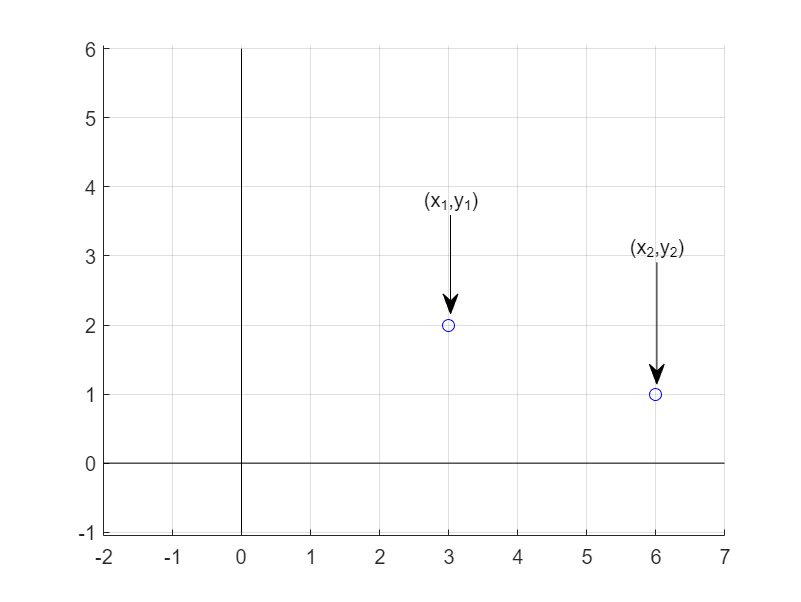

% Define the points (x1,y1) and (x2,y2)
x1 = 3;   
y1 = 2;
x2 = 6; 
y2 = 1;

% Define the x and y ranges
x_min = -2; x_max = 7;
y_min = -1; y_max = 6;

figure(1)
hold on
% Plot x and y-axis
plot([x_min x_max], [0 0],'k')
plot([0 0], [y_min y_max],'k')

% Plot the two given points
plot([x1 x2], [y1 y2],'bo')

axis equal; grid on;

annotation("textarrow",[0.5625 0.5625],[0.6429 0.4786],"String","(x_1,y_1)")
annotation("textarrow",[0.82 0.82],[0.5643 0.3619],"String","(x_2,y_2)")

hold off

First, compute the slope, $m$.


$$m=\frac{y_2 -y_1 }{x_2 -x_1 }=\frac{1-2}{6-3}=\frac{-1}{3}=-\frac{1}{3}$$


Once, you have $m$, you can find $b$. Here is the idea:

Solve eqn (1) for $b$


$$b\;=\;y-m\;x$$
 

Now, plug in $m$ (above) and one of the points on the line, say $\left(3,2\right)$


$$b\;=\;y-m\;x=2-\left(-\frac{1}{3}\right)\left(3\right)=2+1=3\;$$


Therefore, the eqn of the line is


$$y\;=-\frac{1}{3}x+3$$


Here is what computing the slope and y-intercept looks like in code:

Here is a plot of the equation of the line we just found:

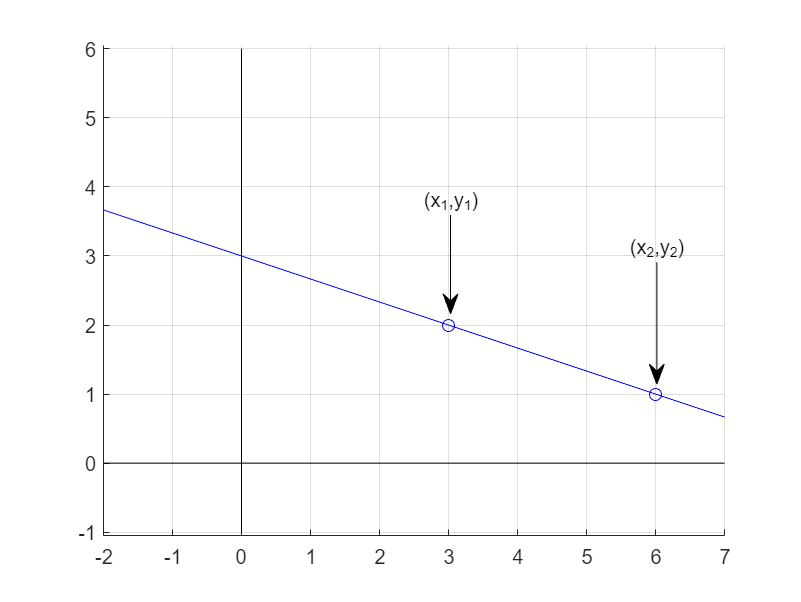

% Compute the slope
m = (y2-y1)/(x2-x1);

% Compute the y-intercept using m and (x1,y1)
b = y1-m*x1;

% List of x and y-values for plotting the line
x_vals = x_min:0.01:x_max;     
y_vals = m*x_vals + b;

figure(2)
hold on
% Plot x and y-axis
plot([x_min x_max], [0 0],'k')
plot([0 0], [y_min y_max],'k')

% Plot the two given points
plot([x1 x2], [y1 y2],'bo')

% Plot the line through these two points
plot(x_vals, y_vals,'b')

axis equal; grid on;

annotation("textarrow",[0.5625 0.5625],[0.6429 0.4786],"String","(x_1,y_1)")
annotation("textarrow",[0.82 0.82],[0.5643 0.3619],"String","(x_2,y_2)")

hold off

## Determining if a point is on a line

Another part of the problem is determining if a point is on the line.

Suppose we want to know if the point $\left(1,3\right)$ is on a line.

The best way to do this is to compare the y-value of the point with the y-value that you would get from plugging the x-value into the equation of the line. 

**Programming Note: Directly comparing an integer (e.g. y-value of the point) with a number that was computed (e.g. the y-value from the line) should not be done.**

To get around this, we can round the y-value to say two decimals using MATLAB's `round` command. For this application, two decimals will not look any different to the user.

The figure below shows that the point $\left(1,3\right)$ does not lie on the line we found above.

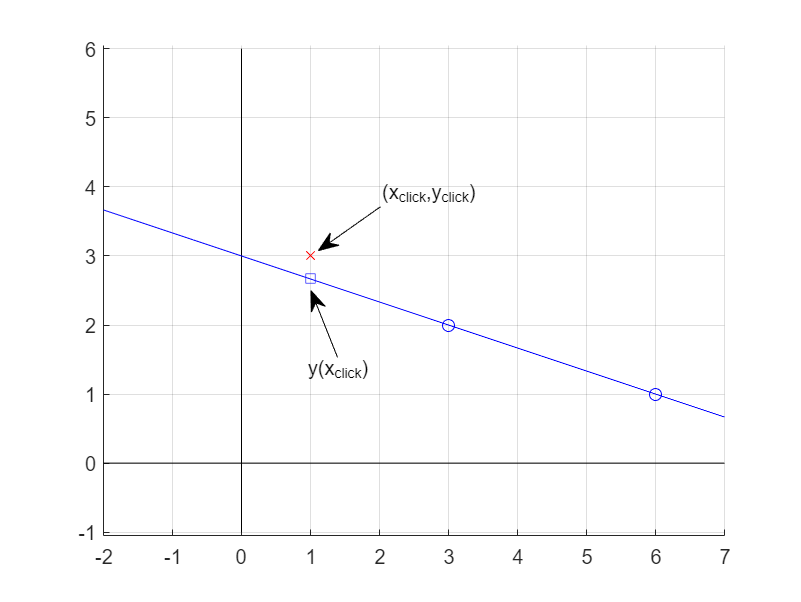

% Define the point to test
x_click = 1;
y_click = 3;

figure(3)
hold on
% Plot x and y-axis
plot([x_min x_max], [0 0],'k')
plot([0 0], [y_min y_max],'k')

% Plot the two given points
plot(x_click, y0,'rx')

% Plot the point to test
plot([x1 x2], [y1 y2],'bo')

% Compute y(x_click)
y_at_x_click = m*x_click + b;

% Plot the point on the line at x=x_click
plot(x_click, y_at_x_click,'bsquare')

% Plot the line through these two points
plot(x_vals, y_vals,'b')

axis equal; grid on;

hold off

annotation("textarrow",[0.4214 0.3882],[0.4064 0.5172],"String","y(x_{click})")
annotation("textarrow",[0.475 0.3974],[0.6566 0.5837],"String","(x_{click},y_{click})")

Here is some code that uses this idea. *Assume we already computed the slope, m, and y-intercept, b, from the previous example.*

## Intersection point of two lines

Let's review how to find the intersection of two lines.

Find the intersection of the following two lines:

$y\;=-\frac{1}{3}x+3$   and   $y\;=2x-1$

The idea is simple, set both equations equal to each other (eliminating y) and solve for x.


$$-\frac{1}{3}x+3\;=2x-1$$



$$-x+9\;=6x-3$$



$$-x-6x=-3-9$$



$$-7x=-12$$



$$x=\frac{12}{7}$$


In your program, you will have to come up with a formula to solve for this x in terms of the slopes and y-intercepts of the two lines.

As an exercise, find the formula for the x-value of the intersection poinnt of the following two lines: 

$y\;=m_1 x+b_1$   and   $y\;=m_2 x-b_2$

## Polygon

A **polygon** is a collection of points (called vertices) that are connected by line segments (called edges).

A **simple polygon** is a polygon that has no intersecting edges. The following polygon is simple:

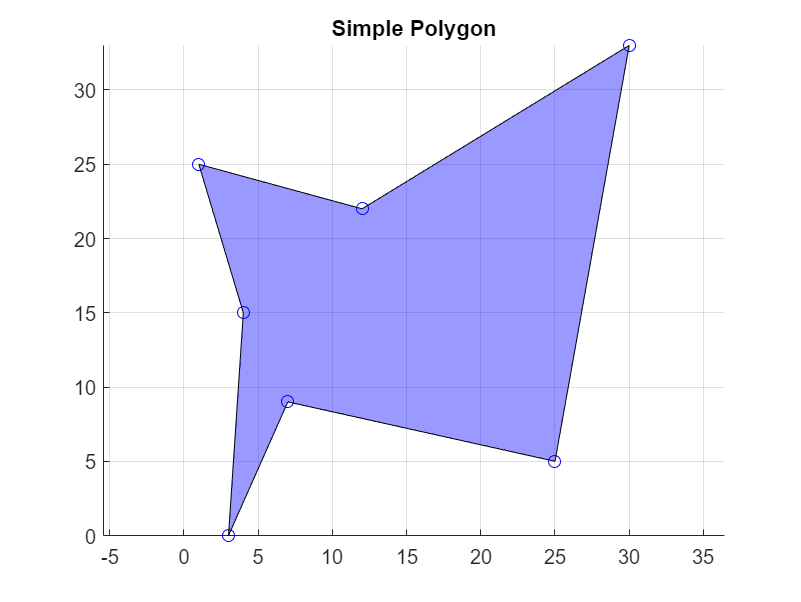

v_x_vals = [3 7 25 30 12  1  4 3];
v_y_vals = [0 9  5 33 22 25 15 0];

figure
hold on
plot(v_x_vals,v_y_vals,'-bo')
fill(v_x_vals,v_y_vals,'b','FaceAlpha',0.4)
title('Simple Polygon')
axis equal
grid on
hold off

Here is an example of a polygon that is not simple:

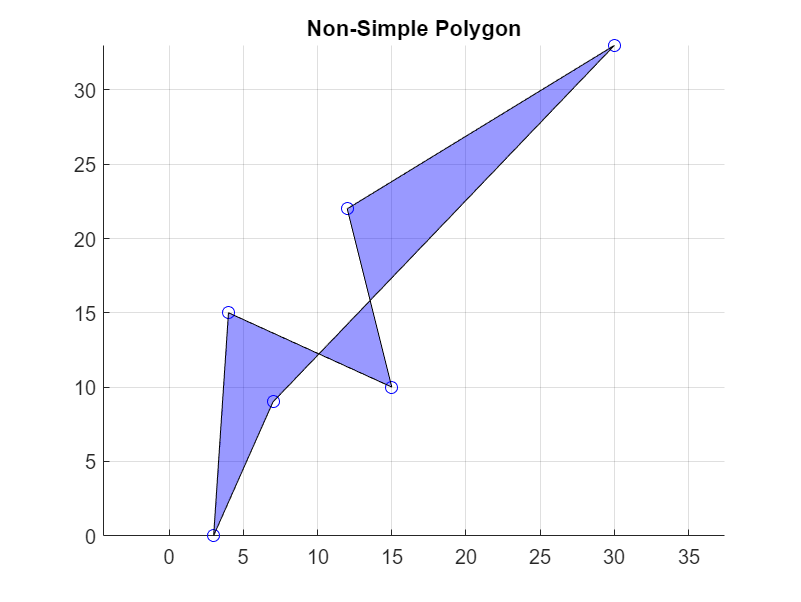

v_x_vals = [3 7 30 12 15  4 3];
v_y_vals = [0 9 33 22 10 15 0];

figure
hold on
plot(v_x_vals,v_y_vals,'-bo')
fill(v_x_vals,v_y_vals,'b','FaceAlpha',0.4)
title('Non-Simple Polygon')
axis equal
grid on
hold off